## **Simulazione guasti sensori**

% Parametri del sensore ideale

t = linspace(0, 10, 100); % tempo
steady_value = 3;
k=3; %tasso di tabilizzazione

% Parametri della sovraelongazione
overshoot_amplitude = 5; % Ampiezza della sovraelongazione
d = 0.2; % Smorzamento
omega = 0.5; % Frequenza della sovraelongazione

ideal_output =5+ steady_value*(1- exp(-k*t))+overshoot_amplitude * exp(-d * t) .* sin(omega * t); % Uscita ideale

% Guasto: Bias
fault_bias = ideal_output - 1; 

% Guasto: Drift
fault_drift = ideal_output + linspace(0, 3, 100); % Offset crescente

% Guasto: Loss of Accuracy
fault_accuracy = ideal_output + randn(1, 100); % Aggiunge rumore gaussiano

% Guasto: Freezing
fault_freezing = ideal_output;
fault_freezing(2:end) = fault_freezing(2);
%fault_freezing(50:end) = fault_freezing(50); % Mantiene valore fisso da metà in poi

% Guasto: Calibration Error (Guadagno errato)
%fault_calibration = 1.5 * input; % Guadagno alterato

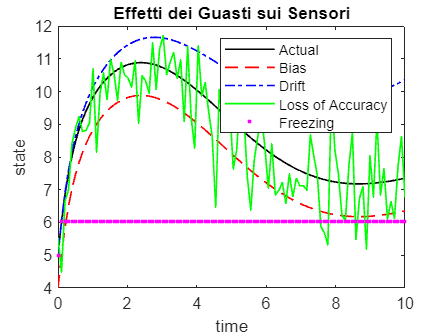

figure;
plot(t, ideal_output, 'k-', 'LineWidth', 1); hold on;
plot(t, fault_bias, 'r--', 'LineWidth', 1);
plot(t, fault_drift, 'b-.', 'LineWidth', 1);
plot(t, fault_accuracy, 'g-', 'LineWidth', 1);
plot(t, fault_freezing, 'm.', 'LineWidth', 1);

legend('Actual', 'Bias', 'Drift', 'Loss of Accuracy','Freezing');
xlabel('time');
ylabel('state');
title('Effetti dei Guasti sui Sensori');
grid off;

mse_bias = mean((ideal_output - fault_bias).^2);
mse_drift = mean((ideal_output - fault_drift).^2);
mse_accuracy = mean((ideal_output - fault_accuracy).^2);
mse_freezing = mean((ideal_output - fault_freezing).^2);

fprintf('MSE Bias: %.2f\n', mse_bias);

MSE Bias: 1.00


fprintf('MSE Drift: %.2f\n', mse_drift);

MSE Drift: 3.02


fprintf('MSE Loss of Accuracy: %.2f\n', mse_accuracy);

MSE Loss of Accuracy: 0.99


fprintf('MSE Freezing: %.2f\n', mse_freezing);

MSE Freezing: 9.48


## Simullazione guasti attuatori

% Output ideale (ad esempio, una sinusoide)
ideal_output_actuator =ideal_output;

% Guasti per gli attuatori
fault_lock_in_place = ideal_output_actuator;
fault_lock_in_place(20:end) = fault_lock_in_place(20);
 % Blocco fisso

fault_float = ideal_output_actuator ;
fault_float(20:end) = 0; % Valore pari a zero

fault_handover = zeros(size(t)); % Preallocazione con la lunghezza di `t`
fault_handover(1:30) = 5*t(1:30);
fault_handover(31:end) = fault_handover(30); % Tasso di crescita rapido (k=5)
%fault_hardover = ideal_output_actuator;
%fault_hardover = atan(17)*t;
%fault_hardover(fault_hardover > 17) = 17; % Limite al valore massimo

fault_loss_effectiveness = ideal_output_actuator;
fault_loss_effectiveness(20:end) = 0.8 * ideal_output_actuator(20:end); % Riduzione guadagno

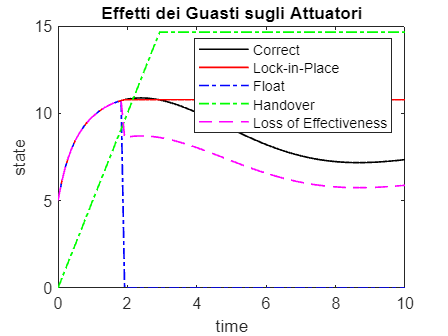

figure;
plot(t, ideal_output_actuator, 'k-', 'LineWidth', 1); hold on;
plot(t, fault_lock_in_place, 'r-', 'LineWidth', 1);
plot(t, fault_float, 'b-.', 'LineWidth', 1);
plot(t, fault_handover, 'g-.', 'LineWidth', 1);
plot(t, fault_loss_effectiveness, 'm--', 'LineWidth', 1);

legend('Correct', 'Lock-in-Place', 'Float', ...
       'Handover', 'Loss of Effectiveness');
xlabel('time');
ylabel('state');
title('Effetti dei Guasti sugli Attuatori');
grid off;